Ct = (5.45e-5) / (4 * 1.225 * pi^3 * 0.065^4)

Ct = 0.0201


Cq = (6.2e-7) / (4 * 1.225 * pi^3 * 0.065^5)

Cq = 0.0035


T = Ct*1.225*pi^3*0.065^4/900

T = 1.5139e-08


Q = Cq*1.225*pi^3*0.065^5/900

Q = 1.7222e-10

ster = [5, 10, 15, 20, 25, 30, 35, 40]/100;
T_avg = [0.08 0.27 0.55 0.92 1.33 1.83 2.32 2.87];
T_single = [0.07 0.24 0.47 0.84 1.28 1.77 2.69 3.38];
M = [0 2.25e-3 5.85e-3 9.15e-3 1.42e-2 1.99e-2 2.61e-2 3.35e-2];

n_t = sqrt(T_avg/T)

n_t = 1.0e+04 *

    0.2299    0.4223    0.6027    0.7796    0.9373    1.0995    1.2379    1.3769



n_st = sqrt(T_single/T)

n_st = 1.0e+04 *

    0.2150    0.3982    0.5572    0.7449    0.9195    1.0813    1.3330    1.4942



n_q = sqrt(M/Q)

n_q = 1.0e+04 *

         0    0.3614    0.5828    0.7289    0.9080    1.0749    1.2310    1.3947


vec_all = [8.00, 27.13, 55.89, 93.75, 135.93, 186.91, 236.79, 292.76];
vec_all = vec_all * 9.81 / 1000;
x_axis = [0.05, 0.10, 0.15, 0.20, 0.25, 0.30, 0.35, 0.40];

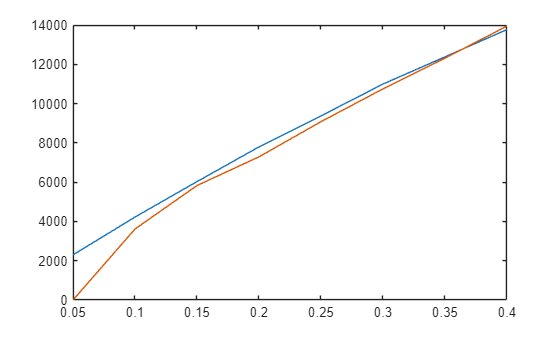

plot(ster, n_t)
hold on 
plot(ster, n_q)
hold off

% Dopasowanie dla sily
u = ster(:);
F = T_avg(:);

% Dopasowanie wielomianu drugiego stopnia:
% F = a*u^2 + b*u + c
p = polyfit(u, F, 2);

a = p(1);
b = p(2);
c = p(3);

fprintf("a = %.8f\n", a);

a = 11.54761905


fprintf("b = %.8f\n", b);

b = 2.90595238


fprintf("c = %.8f\n", c);

c = -0.11875000


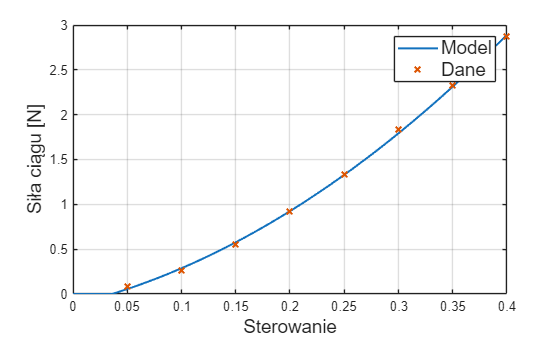


u_plot = linspace(0, 0.40, 200);
F_model = polyval(p, u_plot);

F_model(F_model < 0) = 0;

plot(u_plot, F_model, 'LineWidth', 1.5)
hold on
plot(x_axis, vec_all, 'x', 'LineWidth', 1.5)
grid on
xlabel("Sterowanie", 'FontSize', 14)
ylabel("Siła ciągu [N]", 'FontSize', 14)
legend("Model", "Dane", 'FontSize', 14)

hold off;

% Dopasowanie dla momentów
u = ster(:);
F = M(:);

% Dopasowanie wielomianu drugiego stopnia:
% F = a*u^2 + b*u + c
p = polyfit(u, F, 2);

a = p(1);
b = p(2);
c = p(3);

fprintf("a = %.8f\n", a);

a = 0.16392857


fprintf("b = %.8f\n", b);

b = 0.02169643


fprintf("c = %.8f\n", c);

c = -0.00146339


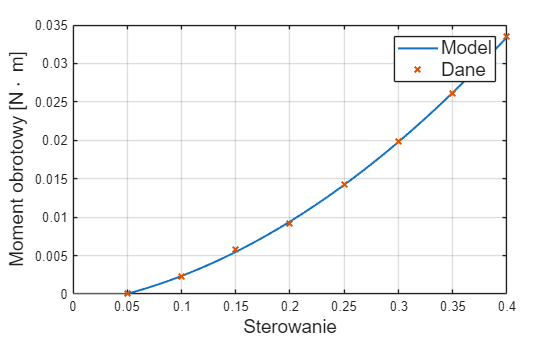


% Wyznaczenie wartości modelu
u_plot = linspace(0, 0.40, 200);
F_model = polyval(p, u_plot);

% Ograniczenie ujemnych wartości momentu
F_model(F_model < 0) = 0;

% Wykres
plot(u_plot, F_model, 'LineWidth', 1.5)
hold on
plot(u, F, 'x', 'LineWidth', 1.5)

grid on
xlabel("Sterowanie", 'FontSize', 14)
ylabel("Moment obrotowy [N\cdot m]", 'FontSize', 14)
legend("Model", "Dane", 'FontSize', 14)

hold off;